# **Week 7 : Examining Carrier Recovery**

The code below examines the ability of digital optical systems to use carrier recovery algorithms to correct for non-idealities in the optical domain when BPSK, QPSK and 16QAM are used as modulation formats

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using BPSK and QPSK.

- An IQ modulator which modulates the output of a laser according to an electrical signal.

### Modulation

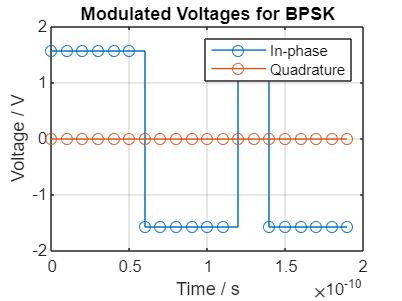

clear all; clearvars;

% Parameters
NSymb = 50000; % No. of symbols 
SpS = 2; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

voltageLevelsBPSK = [-pi/2, pi/2]'; % Discrete voltage levels for BPSK and QPSK
voltageLevelsQPSK = [asin(-1/sqrt(2)), asin(1/sqrt(2))]'; % Discrete voltages for QAM
voltageLevelsQAM = [asin(-3/sqrt(10)), asin(-1/sqrt(10)), asin(1/sqrt(10)), asin(3/sqrt(10))]';
DCOffset = 0; % DC offset of modulated current in V

% -------------------------------------------------------------------------------

% FOR BPSK:
% Generating random bit sequence(s)
sourceBitsBPSK = randi([0 1], NSymb, 1); % Matrix of source bits for BPSK
sourceSymbolsBPSK = pskmod(sourceBitsBPSK, 2); % Maps source bit vector to symbol vector

% Modulating voltage with generated symbols
vI_BPSK = ones(size(sourceSymbolsBPSK)); vQ_BPSK = zeros(size(sourceSymbolsBPSK));

vI_BPSK(real(sourceSymbolsBPSK)>0) = voltageLevelsBPSK(2); % Maps 1 -> pi/2
vI_BPSK(real(sourceSymbolsBPSK)<0) = voltageLevelsBPSK(1); % Maps -1 -pi/2

vI_BPSK_upsampled = repelem(vI_BPSK, SpS, 1); % Upsampling according to SpS
vQ_BPSK_upsampled = repelem(vQ_BPSK, SpS, 1); % Upsampling according to SpS

% Visualising in-phase voltage
stairs(t(1:10*SpS), vI_BPSK_upsampled(1:10*SpS,1), "o-");
hold on
stairs(t(1:10*SpS), vQ_BPSK_upsampled(1:10*SpS,1), "o-");
title("Modulated Voltages for BPSK")
xlabel("Time / s")
ylabel("Voltage / V")
legend("In-phase", "Quadrature")
grid on
hold off

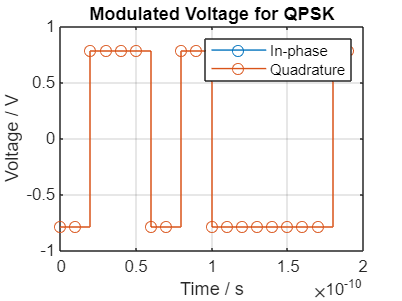


% -------------------------------------------------------------------------------

% FOR QPSK:
% Generating random bit sequence(s)
sourceBitsQPSK = randi([0 1], NSymb*2, 1); % Matrix of source bits for QPSK
sourceIntsQPSK = bit2int(sourceBitsQPSK, 2); % Vector of source bits converted to ints
sourceSymbolsQPSK = pskmod(sourceIntsQPSK, 4, pi/4); % Maps source bit vector to symbol vector

% Modulating voltage with generated symbols
vI_QPSK = ones(size(sourceSymbolsQPSK)); vQ_QPSK = zeros(size(sourceSymbolsQPSK));

vI_QPSK(real(sourceSymbolsQPSK)>0) = voltageLevelsQPSK(2); % Maps 1 -> asin(1/sqrt(2))
vI_QPSK(real(sourceSymbolsQPSK)<0) = voltageLevelsQPSK(1); % Maps -1 -> asin(-1/sqrt(2))
vQ_QPSK(imag(sourceSymbolsQPSK)>0) = voltageLevelsQPSK(2); % Maps 1 -> asin(1/sqrt(2))
vQ_QPSK(imag(sourceSymbolsQPSK)<0) = voltageLevelsQPSK(1); % Maps -1 -> asin(-1/sqrt(2))

vI_QPSK_upsampled = repelem(vI_QPSK, SpS, 1); % Upsampling according to SpS
vQ_QPSK_upsampled = repelem(vQ_QPSK, SpS, 1); % Upsampling according to SpS

% Visualising in-phase and quadrature voltage
stairs(t(1:10*SpS), vI_QPSK_upsampled(1:10*SpS,1), "o-");
hold on
stairs(t(1:10*SpS), vQ_QPSK_upsampled(1:10*SpS,1), "o-");
title("Modulated Voltage for QPSK")
xlabel("Time / s")
ylabel("Voltage / V")
legend("In-phase", "Quadrature")
grid on
hold off

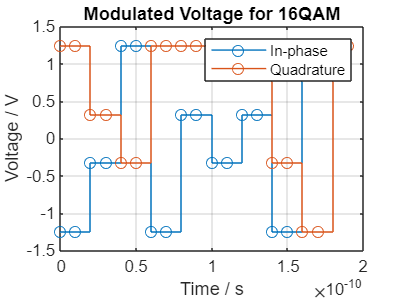


% -----------------------------------------

% For 16QAM
sourceBitsQAM = randi([0 1], NSymb*4, 1); % Matrix of source bits for 16QAM
sourceIntsQAM = bit2int(sourceBitsQAM, 4); % Vector of source bits converted to ints
sourceSymbolsQAM = qammod(sourceIntsQAM, 16, UnitAveragePower=true); % Maps source bit vector to symbol vector

% Modulating voltage with generated symbols
vI_QAM = ones(size(sourceSymbolsQAM)); vQ_QAM = zeros(size(sourceSymbolsQAM));

QAMBoundaries = [-2/sqrt(10), 0, 2/sqrt(10)];

vI_QAM(real(sourceSymbolsQAM)<=-2/sqrt(10)) = voltageLevelsQAM(1); 
vI_QAM(real(sourceSymbolsQAM)>-2/sqrt(10) & real(sourceSymbolsQAM)<=0) = voltageLevelsQAM(2);
vI_QAM(real(sourceSymbolsQAM)>0 & real(sourceSymbolsQAM)<=2/sqrt(10)) = voltageLevelsQAM(3); 
vI_QAM(real(sourceSymbolsQAM)>2/sqrt(10)) = voltageLevelsQAM(4); 

vQ_QAM(imag(sourceSymbolsQAM)<=-2/sqrt(10)) = voltageLevelsQAM(1); 
vQ_QAM(imag(sourceSymbolsQAM)>-2/sqrt(10) & imag(sourceSymbolsQAM)<=0) = voltageLevelsQAM(2);
vQ_QAM(imag(sourceSymbolsQAM)>0 & imag(sourceSymbolsQAM)<=2/sqrt(10)) = voltageLevelsQAM(3); 
vQ_QAM(imag(sourceSymbolsQAM)>2/sqrt(10)) = voltageLevelsQAM(4); 

vI_QAM_upsampled = repelem(vI_QAM, SpS, 1); % Upsampling according to SpS
vQ_QAM_upsampled = repelem(vQ_QAM, SpS, 1); % Upsampling according to SpS

% Visualising in-phase and quadrature voltage
stairs(t(1:10*SpS), vI_QAM_upsampled(1:10*SpS,1), "o-");
hold on
stairs(t(1:10*SpS), vQ_QAM_upsampled(1:10*SpS,1), "o-");
title("Modulated Voltage for 16QAM")
xlabel("Time / s")
ylabel("Voltage / V")
legend("In-phase", "Quadrature")
grid on
hold off

### Pulse Shaping

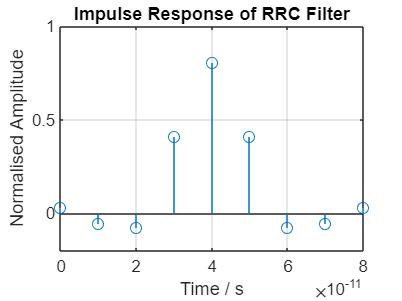

% RRC filter parameters
filterSpan = 4; % Span of RRC filter in no. of symbols
rollOff = 0.5;
filterResponse = rcosdesign(rollOff, filterSpan, SpS)';
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
v_shaped_t = [0:1:samples-1]*T;

% Visualisation of RRC filter
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
% filterResponse_t_interp = [0:0.25:filterSpan*SpS]*T;
% filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
% plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");
stem(filterResponse_t, filterResponse, '-o');
title('Impulse Response of RRC Filter');
xlabel('Time / s');
ylabel('Normalised Amplitude');
grid on

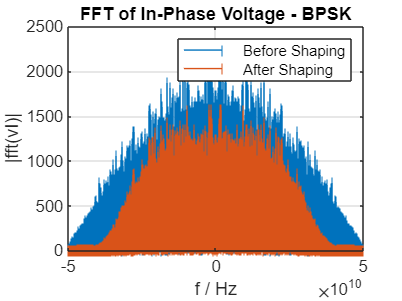


% ---------------------------------------------------------------------------

% FOR BPSK:
% Using RRC filter to shape vI and vQ

vI_BPSK_shaped = upfirdn(vI_BPSK, filterResponse, SpS, 1); vQ_BPSK_shaped = upfirdn(vQ_BPSK, filterResponse, SpS, 1);

% Frequency spectrum of voltage waveforms before and after filtering
fft_vI_BPSK = fftshift(fft(vI_BPSK_upsampled(:,1))); % FFT of noisy signal before shaping 
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

fft_vI_BPSK_shaped = fftshift(fft(vI_BPSK_shaped(:,1))); % FFT of noisy signal after shaping
freqArr_shaped = [-samples/2:samples/2 - 1]/(T*samples);

stem(freqArr, abs(fft_vI_BPSK), "|");
hold on
stem(freqArr_shaped, abs(fft_vI_BPSK_shaped), "|");
title("FFT of In-Phase Voltage - BPSK");
xlabel("f / Hz");
ylabel("|fft(vI)|");
legend("Before Shaping", "After Shaping")
hold off
grid on

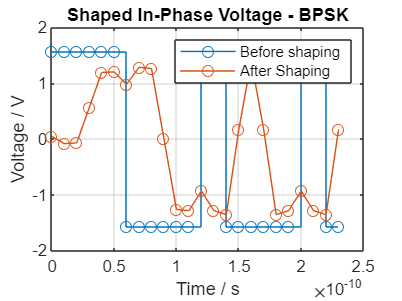


% Visualising pulse-shaped voltages
stairs(v_shaped_t(1:10*SpS + filterSpan), vI_BPSK_upsampled(1:10*SpS + filterSpan,1), "o-");
hold on
plot(v_shaped_t(1:10*SpS + filterSpan), vI_BPSK_shaped(1:10*SpS + filterSpan,1), "o-");
title("Shaped In-Phase Voltage - BPSK");
ylabel("Voltage / V");
xlabel('Time / s');
legend("Before shaping", "After Shaping");
grid on
hold off

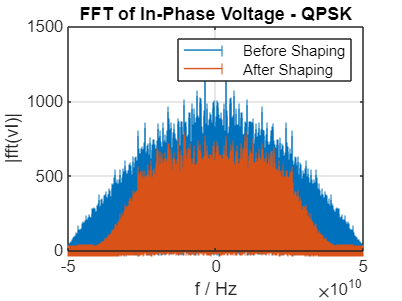


% -------------------------------------------------------------------------

% FOR QPSK:
% Using RRC filter to shape vI and vQ

vI_QPSK_shaped = upfirdn(vI_QPSK, filterResponse, SpS, 1); vQ_QPSK_shaped = upfirdn(vQ_QPSK, filterResponse, SpS, 1);

% Frequency spectrum of voltage waveforms before filtering
fft_vI_QPSK = fftshift(fft(vI_QPSK_upsampled(:,1))); % FFT of noisy signal before shaping
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

fft_vI_QPSK_shaped = fftshift(fft(vI_QPSK_shaped(:,1))); % FFT of nosiy signal after shaping
freqArr_shaped = [-samples/2:samples/2 - 1]/(T*samples);

stem(freqArr, abs(fft_vI_QPSK), "|");
hold on
stem(freqArr_shaped, abs(fft_vI_QPSK_shaped), "|");
title("FFT of In-Phase Voltage - QPSK");
xlabel("f / Hz");
ylabel("|fft(vI)|");
legend("Before Shaping", "After Shaping");
hold off
grid on

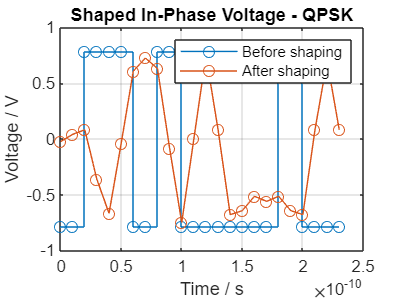


% Visualising pulse-shaped voltages
stairs(v_shaped_t(1:10*SpS + filterSpan), vI_QPSK_upsampled(1:10*SpS + filterSpan,1), "o-");
hold on
plot(v_shaped_t(1:10*SpS + filterSpan), vI_QPSK_shaped(1:10*SpS + filterSpan,1), "o-");
title("Shaped In-Phase Voltage - QPSK");
ylabel("Voltage / V");
xlabel('Time / s');
legend("Before shaping", "After shaping");
grid on
hold off

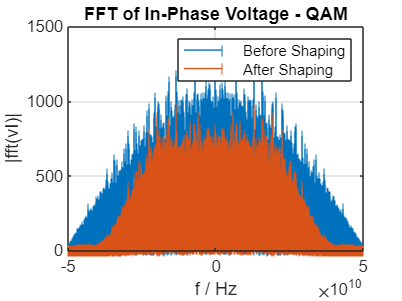



% -------------------------------------------------------------------------

% FOR 16-QAM:
% Using RRC filter to shape vI and vQ

vI_QAM_shaped = upfirdn(vI_QAM, filterResponse, SpS, 1); vQ_QAM_shaped = upfirdn(vQ_QAM, filterResponse, SpS, 1);

% Frequency spectrum of voltage waveforms before filtering
fft_vI_QAM = fftshift(fft(vI_QAM_upsampled(:,1))); % FFT of noisy signal before shaping
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

fft_vI_QAM_shaped = fftshift(fft(vI_QAM_shaped(:,1))); % FFT of nosiy signal after shaping
freqArr_shaped = [-samples/2:samples/2 - 1]/(T*samples);

stem(freqArr, abs(fft_vI_QAM), "|");
hold on
stem(freqArr_shaped, abs(fft_vI_QAM_shaped), "|");
title("FFT of In-Phase Voltage - QAM");
xlabel("f / Hz");
ylabel("|fft(vI)|");
legend("Before Shaping", "After Shaping");
hold off
grid on

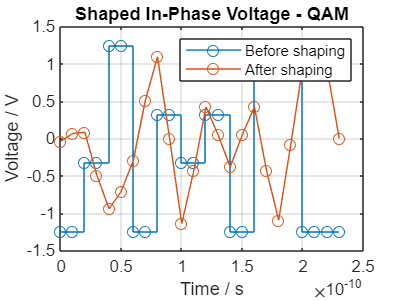


% Visualising pulse-shaped voltages
stairs(v_shaped_t(1:10*SpS + filterSpan), vI_QAM_upsampled(1:10*SpS + filterSpan,1), "o-");
hold on
plot(v_shaped_t(1:10*SpS + filterSpan), vI_QAM_shaped(1:10*SpS + filterSpan,1), "o-");
title("Shaped In-Phase Voltage - QAM");
ylabel("Voltage / V");
xlabel('Time / s');
legend("Before shaping", "After shaping");
grid on
hold off


bandwidth = 0.5*(1+rollOff)/T

bandwidth = 7.5000e+10

### IQ Modulation

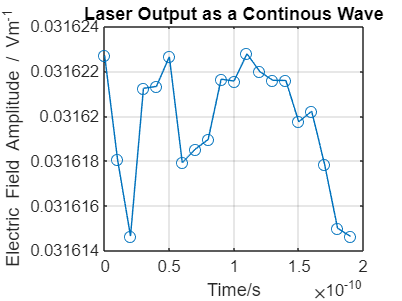

% Initialising laser parameters
lineWidth = 1e6;
laserPw_dBm = 0;
laserPw_Lin = 1e-3*10^(laserPw_dBm/10);

% Generating output from laser modelled as a contniuous-wave source
laserE = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 1); % Laser output to be used with unshaped signals
laserE_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 1); % Laser output to be used with shaped signals

% Visualising output from laser
plot(t(1:20), real(laserE(1:20)), "o-");
title("Laser Output as a Continous Wave");
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}");
grid on

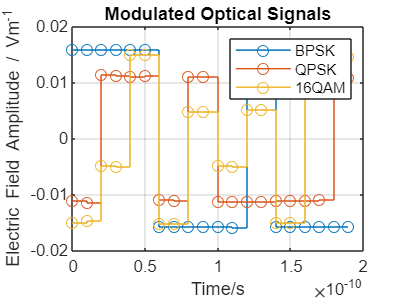


% Modulating optical signal using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi

% Unshaped Signals
modOpticSigBPSK = IQModulatorModified(vI_BPSK_upsampled, vQ_BPSK_upsampled, laserE, Vpi);
modOpticSigQPSK = IQModulatorModified(vI_QPSK_upsampled, vQ_QPSK_upsampled, laserE, Vpi);
modOpticSigQAM = IQModulatorModified(vI_QAM_upsampled, vQ_QAM_upsampled, laserE, Vpi);

% Shaped Signals
modOpticSigBPSK_shaped = IQModulatorModified(vI_BPSK_shaped, vQ_BPSK_shaped, laserE_shaped, Vpi);
modOpticSigQPSK_shaped = IQModulatorModified(vI_QPSK_shaped, vQ_QPSK_shaped, laserE_shaped, Vpi);
modOpticSigQAM_shaped = IQModulatorModified(vI_QAM_shaped, vQ_QAM_shaped, laserE_shaped, Vpi);

% Visualising modulated optical signals
stairs(t(1:10*SpS), real(modOpticSigBPSK(1:10*SpS,1)), "o-");
hold on
stairs(t(1:10*SpS), real(modOpticSigQPSK(1:10*SpS,1)), "o-");
stairs(t(1:10*SpS), real(modOpticSigQAM(1:10*SpS,1)), "o-");
title("Modulated Optical Signals")
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}")
legend("BPSK", "QPSK", "16QAM")
grid on
hold off

## Optical Channel

## Receiver

### Optical Front-End

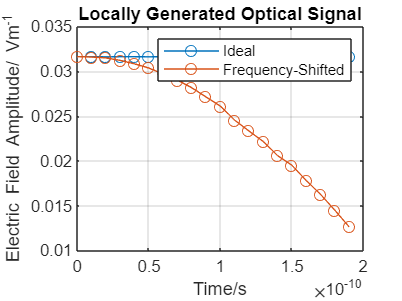

% Generating Local optical signal for coherent detection
carr_freq = 3e8/(1550e-9); % Carrier frequency in ms-1
freq_offset = 1e9; % LO signal frequency offset

Elo = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 1); % LO signal with non-zero linewidth for unshaped signals
Elo_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 1); % LO signal with non-zero linewidth for shaped signals
Elo_shifted = LOFrequencyShift(Elo, freq_offset, T); % Frequency-shifted LO signal for unshaped information signal
Elo_shaped_shifted = LOFrequencyShift(Elo_shaped, freq_offset, T); % Frequency-shifted LO signal for shaped information signal

% Visualising locally generated optical signal
plot(t(1:20), real(Elo(1:20,1)), "-o");
hold on
plot(t(1:20), real(Elo_shifted(1:20,1)), "-o");
title("Locally Generated Optical Signal");
xlabel("Time/s")
ylabel("Electric Field Amplitude/ Vm^{-1}")
legend("Ideal", "Frequency-Shifted")
hold off
grid on

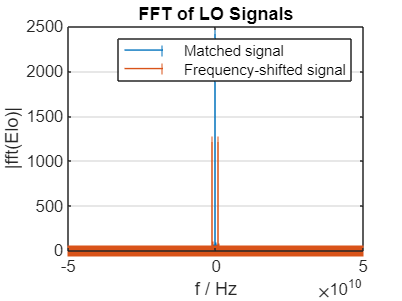


% Visualising FFTs of original and frequency shifted LO laser signal
fft_Elo = fftshift(fft(Elo(:,1))); % FFT of original LO signal
fft_Elo_shifted = fftshift(fft(real(Elo_shifted(:,1)))); % FFT of frequency-shifted LO signal
freqArr_Elo = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

stem(freqArr_Elo, abs(fft_Elo), "|");
hold on
stem(freqArr_Elo, abs(fft_Elo_shifted), "|");
title("FFT of LO Signals");
xlabel("f / Hz");
ylabel("|fft(Elo)|");
legend("Matched signal", "Frequency-shifted signal");
hold off
grid on



% Generating output from optical front-end
eta_ph = 0.3; % Responsivity of photodetectors

count=1;
for i=1:size(modOpticSigBPSK,2)
    % Unshaped Signals
    OpticFEOutBPSK(:,count:count+1) = OpticalFrontEnd(modOpticSigBPSK(:,i), Elo_shifted, eta_ph, 1);
    OpticFEOutQPSK(:,count:count+1) = OpticalFrontEnd(modOpticSigQPSK(:,i), Elo_shifted, eta_ph, 1);
    OpticFEOutQAM(:,count:count+1) = OpticalFrontEnd(modOpticSigQAM(:,i), Elo_shifted, eta_ph, 1);
    
    % Shaped signals
    OpticFEOutBPSK_shaped(:,count:count+1) = OpticalFrontEnd(modOpticSigBPSK_shaped(:,i), Elo_shaped_shifted, eta_ph, 1);
    OpticFEOutQPSK_shaped(:,count:count+1) = OpticalFrontEnd(modOpticSigQPSK_shaped(:,i), Elo_shaped_shifted, eta_ph, 1);
    OpticFEOutQAM_shaped(:,count:count+1) = OpticalFrontEnd(modOpticSigQAM_shaped(:,i), Elo_shaped_shifted, eta_ph, 1);
    
    % Test signals with ideal LO signal
    testFEOutBPSK(:,count:count+1) = OpticalFrontEnd(modOpticSigBPSK(:,i), laserE, eta_ph, 1);
    testFEOutQPSK(:,count:count+1) = OpticalFrontEnd(modOpticSigQPSK(:,i), laserE, eta_ph, 1);
    testFEOutQAM(:,count:count+1) = OpticalFrontEnd(modOpticSigQAM(:,i), laserE, eta_ph, 1);

    count=count+2;
end

% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC

% Amplification and separation of in-phase and quadrature components of the two polarizations
% BPSK
OpticFEOutBPSK_I = TIA_Gain*OpticFEOutBPSK(:,1:2:end); OpticFEOutBPSK_Q = TIA_Gain*OpticFEOutBPSK(:,2:2:end); % Unshaped with shifted LO 
OpticFEOutBPSK_shaped_I = TIA_Gain*OpticFEOutBPSK_shaped(:,1:2:end); OpticFEOutBPSK_shaped_Q = TIA_Gain*OpticFEOutBPSK_shaped(:,2:2:end); % Shaped with shifted LO
testFEOutBPSK_I = TIA_Gain*testFEOutBPSK(:,1:2:end); testFEOutBPSK_Q = TIA_Gain*testFEOutBPSK(:,2:2:end); % With ideal LO

% QPSK
OpticFEOutQPSK_I = TIA_Gain*OpticFEOutQPSK(:,1:2:end); OpticFEOutQPSK_Q = TIA_Gain*OpticFEOutQPSK(:,2:2:end); % Unshaped with shifted LO 
OpticFEOutQPSK_shaped_I = TIA_Gain*OpticFEOutQPSK_shaped(:,1:2:end); OpticFEOutQPSK_shaped_Q = TIA_Gain*OpticFEOutQPSK_shaped(:,2:2:end); % Shaped with shifted LO
testFEOutQPSK_I = TIA_Gain*testFEOutQPSK(:,1:2:end); testFEOutQPSK_Q = TIA_Gain*testFEOutQPSK(:,2:2:end); % With ideal LO

% 16-QAM
OpticFEOutQAM_I = TIA_Gain*OpticFEOutQAM(:,1:2:end); OpticFEOutQAM_Q = TIA_Gain*OpticFEOutQAM(:,2:2:end); % Unshaped with shifted LO 
OpticFEOutQAM_shaped_I = TIA_Gain*OpticFEOutQAM_shaped(:,1:2:end); OpticFEOutQAM_shaped_Q = TIA_Gain*OpticFEOutQAM_shaped(:,2:2:end); % Shaped with shifted LO
testFEOutQAM_I = TIA_Gain*testFEOutQAM(:,1:2:end); testFEOutQAM_Q = TIA_Gain*testFEOutQAM(:,2:2:end); % With ideal LO

## DSP

### Scaling and Downsampling

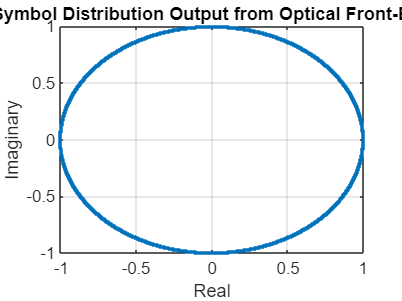

% Scaling factor between output of IQM and output of optical front-end
laserEMag = sqrt(laserPw_Lin);
% scaleFactor=1;
scaleFactor = TIA_Gain*eta_ph*laserEMag*laserEMag/2;

% Cancelling the scaling factor and downsampling:
% BPSK
voltageBPSK_I = OpticFEOutBPSK_I(1:SpS:end,:)/scaleFactor; voltageBPSK_Q = OpticFEOutBPSK_Q(1:SpS:end,:)/scaleFactor; % Unshaped with shifted LO
voltageBPSK_shaped_I = upfirdn(OpticFEOutBPSK_shaped_I, filterResponse, 1, SpS); voltageBPSK_shaped_I = voltageBPSK_shaped_I(filterSpan + 1:end - filterSpan,:); % Shaped with shifted LO
voltageBPSK_shaped_Q = upfirdn(OpticFEOutBPSK_shaped_Q, filterResponse, 1, SpS); voltageBPSK_shaped_Q = voltageBPSK_shaped_Q(filterSpan + 1:end - filterSpan,:); % Shaped with shifted LO
testBPSK_I = testFEOutBPSK_I(1:SpS:end,:)/scaleFactor; testBPSK_Q = testFEOutBPSK_Q(1:SpS:end,:)/scaleFactor; % With ideal LO

% QPSK
voltageQPSK_I = OpticFEOutQPSK_I(1:SpS:end,:)/scaleFactor; voltageQPSK_Q = OpticFEOutQPSK_Q(1:SpS:end,:)/scaleFactor; % Unshaped with shifted LO
voltageQPSK_shaped_I = upfirdn(OpticFEOutQPSK_shaped_I, filterResponse, 1, SpS); voltageQPSK_shaped_I = voltageQPSK_shaped_I(filterSpan + 1:end - filterSpan,:); % Shaped with shifted LO
voltageQPSK_shaped_Q = upfirdn(OpticFEOutQPSK_shaped_Q, filterResponse, 1, SpS); voltageQPSK_shaped_Q = voltageQPSK_shaped_Q(filterSpan + 1:end - filterSpan,:); % Shaped with shifted LO
testQPSK_I = testFEOutQPSK_I(1:SpS:end,:)/scaleFactor; testQPSK_Q = testFEOutQPSK_Q(1:SpS:end,:)/scaleFactor; % With ideal LO

% 16-QAM
voltageQAM_I = OpticFEOutQAM_I(1:SpS:end,:)/scaleFactor; voltageQAM_Q = OpticFEOutQAM_Q(1:SpS:end,:)/scaleFactor; % Unshaped with shifted LO
voltageQAM_shaped_I = upfirdn(OpticFEOutQAM_shaped_I, filterResponse, 1, SpS); voltageQAM_shaped_I = voltageQAM_shaped_I(filterSpan + 1:end - filterSpan,:); % Shaped with shifted LO
voltageQAM_shaped_Q = upfirdn(OpticFEOutQAM_shaped_Q, filterResponse, 1, SpS); voltageQAM_shaped_Q = voltageQAM_shaped_Q(filterSpan + 1:end - filterSpan,:); % Shaped with shifted LO
testQAM_I = testFEOutQAM_I(1:SpS:end,:)/scaleFactor; testQAM_Q = testFEOutQAM_Q(1:SpS:end,:)/scaleFactor; % With ideal LO

% Visualisation of symbol distributions after scaling and downsampling
plot(voltageQPSK_I, voltageQPSK_Q, '.');
hold on
% plot(testQPSK_I, testQPSK_Q, '.');
% plot(testQAM_I, testQAM_Q, '.');
title("Symbol Distribution Output from Optical Front-End");
xlabel("Real")
ylabel("Imaginary")
% legend("BPSK", "QPSK", "16QAM")
hold off
grid on

### Carrier Recovery

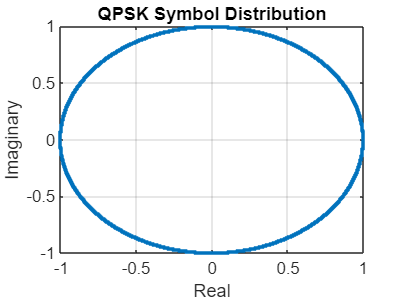

% Implementing carrier recovery algorithm
% NOTE: Carrier recovery algorithms must be applied after downsampling, i.e. SpS=1

% Frequency recovery
% For BPSK:
[voltageBPSK_freq, Delta_f_BPSK] = FrequencyRecovery(voltageBPSK_I+1i*voltageBPSK_Q, Rs); % Unshaped
[voltageBPSK_shaped_freq, Delta_f_BPSK_shaped] = FrequencyRecovery(voltageBPSK_shaped_I+1i*voltageBPSK_shaped_Q, Rs); % Shaped

% For QPSK:
[voltageQPSK_freq, Delta_f_QPSK] = FrequencyRecovery(voltageQPSK_I+1i*voltageQPSK_Q, Rs); % Unshaped
[voltageQPSK_shaped_freq, Delta_f_QPSK_shaped] = FrequencyRecovery(voltageQPSK_shaped_I+1i*voltageQPSK_shaped_Q, Rs); % Shaped

% For 16QAM:
[voltageQAM_freq, Delta_f_QAM] = FrequencyRecovery(voltageQAM_I+1i*voltageQAM_Q, Rs); % Unshaped
[voltageQAM_shaped_freq, Delta_f_QAM_shaped] = FrequencyRecovery(voltageQAM_shaped_I+1i*voltageQAM_shaped_Q, Rs); % Shaped


% Visualisation of spectra before and after frequency recovery
% % For BPSK:
% fft_BPSK_before = fftshift(fft(voltageBPSK_shaped_I(:,1))); % FFT of signal before recovery
% fft_BPSK_after = fftshift(fft(real(voltageBPSK_shaped(:,1)))); % FFT of signal after recovery
% freqArr = [-NSymb/2:NSymb/2 - 1]*Rs/NSymb;
% 
% stem(freqArr, abs(fft_BPSK_before), "|");
% hold on
% stem(freqArr, abs(fft_BPSK_after), "|");
% title("FFT of BPSK Information Signal");
% xlabel("f / Hz");
% ylabel("|fft(Info_signal)|");
% legend("Before Recovery", "After Recovery");
% grid on
% hold off
% 
% % For QPSK:
% fft_QPSK_before = fftshift(fft(voltageQPSK_shaped_I(:,1))); % FFT of signal before recovery
% fft_QPSK_after = fftshift(fft(real(voltageQPSK_shaped(:,1)))); % FFT of signal after recovery
% 
% stem(freqArr, abs(fft_QPSK_before), "|");
% hold on
% stem(freqArr, abs(fft_QPSK_after), "|");
% title("FFT of QPSK Information Signal");
% xlabel("f / Hz");
% ylabel("|fft(Info_signal)|");
% legend("Before Recovery", "After Recovery");
% grid on
% hold off

% Visualising symbol distributions after frequency recovery
% QPSK
plot (voltageQPSK_freq, ".");
title("QPSK Symbol Distribution");
xlabel("Real");
ylabel("Imaginary");
grid on

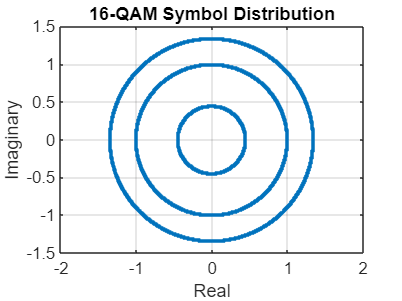


% 16QAM
plot (voltageQAM_freq, ".");
title("16-QAM Symbol Distribution");
xlabel("Real");
ylabel("Imaginary");
grid on



% Phase recovery using the Viterbi and Viterbi algorithm
ViterbiParams = struct("N", 100, "PEstimate", true); % Parameters to be used with the Viterbi algorithm
BPSParams = struct("B", 6, "N", 10, "PEstimate", true); % BPS parameters

% For BPSK
[voltageBPSK, PEstimate_BPSK] = ViterbiCPR(voltageBPSK_freq, 2*lineWidth, Rs, 0, 1, 1, 4, ViterbiParams); % Unshaped
[voltageBPSK_shaped, PEstimate_BPSK_shaped] = ViterbiCPR(voltageBPSK_shaped_freq, 2*lineWidth, Rs, 0, 1, 1, 4, ViterbiParams); % Shaped

% For QPSK
[voltageQPSK, PEstimate_QPSK] = ViterbiCPR(voltageQPSK_freq, 2*lineWidth, Rs, 0, 1, 1, 4, ViterbiParams); % Unshaped
[voltageQPSK_shaped, PEstimate_QPSK_shaped] = ViterbiCPR(voltageQPSK_shaped_freq, 2*lineWidth, Rs, 0, 1, 1, 4, ViterbiParams); % Shaped


% For 16QAM
[voltageQAM, PEstimate_QAM] = BPS(voltageQAM_freq, 16, 1, BPSParams); % Unshaped
[voltageQAM_shaped, PEstimate_QAM_shaped] = BPS(voltageQAM_shaped_freq, 16, 1, BPSParams); % Shaped


% Visualisation of spectra before and after phase recovery recovery
% For BPSK:
% fft_BPSK_before = fftshift(fft(voltageBPSK_shaped_I(:,1))); % FFT of signal before recovery
% fft_BPSK_after = fftshift(fft(real(voltageBPSK_shaped(:,1)))); % FFT of signal after recovery
% freqArr = [-NSymb/2:NSymb/2 - 1]*Rs/NSymb;
% 
% stem(freqArr, abs(fft_BPSK_before), "|");
% hold on
% stem(freqArr, abs(fft_BPSK_after), "|");
% title("FFT of BPSK Information Signal");
% xlabel("f / Hz");
% ylabel("|fft(Info_signal)|");
% legend("Before Recovery", "After Recovery");
% grid on
% hold off
% 
% % For QPSK:
% fft_QPSK_before = fftshift(fft(voltageQPSK_shaped_I(:,1))); % FFT of signal before recovery
% fft_QPSK_after = fftshift(fft(real(voltageQPSK_shaped(:,1)))); % FFT of signal after recovery
% 
% stem(freqArr, abs(fft_QPSK_before), "|");
% hold on
% stem(freqArr, abs(fft_QPSK_after), "|");
% title("FFT of QPSK Information Signal");
% xlabel("f / Hz");
% ylabel("|fft(Info_signal)|");
% legend("Before Recovery", "After Recovery");
% grid on
% hold off


### Decoding and Decision

% BPSK
% Before carrier recovery
decodedSymbolsBPSK_before = voltageBPSK_I+1i*voltageBPSK_Q;
decodedBitsBPSK_before = pskdemod(decodedSymbolsBPSK_before, 2);
biterr(decodedBitsBPSK_before, sourceBitsBPSK)

ans = 24977


% After carrier recovery
decodedSymbolsBPSK_after = voltageBPSK;
decodedBitsBPSK_after = pskdemod(decodedSymbolsBPSK_after, 2);
biterr(decodedBitsBPSK_after, sourceBitsBPSK)

ans = 0


% Test 
testSymbolsBPSK = testBPSK_I + 1i*testBPSK_Q;
testBitsBPSK = pskdemod(testSymbolsBPSK, 2);
biterr(testBitsBPSK, sourceBitsBPSK)

ans = 0


% --------------------------------------------------------------------------------------------

% QPSK
% Before carrier recovery
decodedSymbolsQPSK_before = voltageQPSK_I+1i*voltageQPSK_Q;
decodedIntsQPSK_before = pskdemod(decodedSymbolsQPSK_before, 4, pi/4);
decodedBitsQPSK_before = int2bit(decodedIntsQPSK_before, 2);
biterr(decodedBitsQPSK_before, sourceBitsQPSK)

ans = 50031


% After carrier recovery
decodedSymbolsQPSK_after = voltageQPSK;
decodedIntsQPSK_after = pskdemod(decodedSymbolsQPSK_after, 4, pi/4);
decodedBitsQPSK_after = int2bit(decodedIntsQPSK_after, 2);
biterr(decodedBitsQPSK_after, sourceBitsQPSK)

ans = 0


% Test 
testSymbolsQPSK = testQPSK_I + 1i*testQPSK_Q;
testIntsQPSK = pskdemod(testSymbolsQPSK, 4, pi/4);
testBitsQPSK = int2bit(testIntsQPSK, 2);
biterr(testBitsQPSK, sourceBitsQPSK)

ans = 0


% --------------------------------------------------------------------------------------------

% 16QAM
% Before carrier recovery
decodedSymbolsQAM_before = voltageQAM_I+1i*voltageQAM_Q;
decodedIntsQAM_before = qamdemod(decodedSymbolsQAM_before, 16, UnitAveragePower=true);
decodedBitsQAM_before = int2bit(decodedIntsQAM_before, 4);
biterr(decodedBitsQAM_before, sourceBitsQAM)

ans = 82751


% After carrier recovery
decodedSymbolsQAM_after = voltageQAM;
decodedIntsQAM_after = qamdemod(decodedSymbolsQAM_after, 16, UnitAveragePower=true);
decodedBitsQAM_after = int2bit(decodedIntsQAM_after, 4);
biterr(decodedBitsQAM_after, sourceBitsQAM)

ans = 0


% Test 
testSymbolsQAM = testQAM_I + 1i*testQAM_Q;
testIntsQAM = qamdemod(testSymbolsQAM, 16, UnitAveragePower=true);
testBitsQAM = int2bit(testIntsQAM, 4);
biterr(testBitsQAM, sourceBitsQAM)

ans = 0

### Computing BER

% for i=1:2
%     [~, BER_BPSK(i)] = biterr(decodedBitsBPSK(:,i), sourceBitsBPSK(1+NRemove_BPSK:end,i));
%     [~, BER_QPSK(i)] = biterr(decodedBitsQPSK(:,i), sourceBitsQPSK(1+NRemove_QPSK*2:end,i));
%     [~, BER_QAM(i)] = biterr(decodedBitsQAM(:,i), sourceBitsQAM(1+NRemove_QAM*4:end,i));
%     [~, BER_BPSK_PMD(i)] = biterr(decodedBitsBPSK_PMD, sourceBitsBPSK);
%     [~, BER_QPSK_PMD(i)] = biterr(decodedBitsQPSK_PMD, sourceBitsQPSK);
%     [~, BER_QAM_PMD(i)] = biterr(decodedBitsQAM_PMD, sourceBitsQAM);
% end
% 
% BER_BPSK
% BER_QPSK
% BER_QAM
% BER_BPSK_PMD
% BER_QPSK_PMD
% BER_QAM_PMD